% Definir la variable simbólica para la función de transferencia
s = tf('s');

% Funciones de transferencia individuales
FdT_Planta = 1/(7.5*s^2 + 6.5*s + 1);
FdT_Sensor = 0.01;
FdT_Ventilador = -0.0038/(s + 0.007);
FdT_Comparador = 16.67;
FdT_Inversor=-1;

% Definir la función de transferencia a lazo abierto (GH)
G=FdT_Planta*FdT_Ventilador*FdT_Comparador*FdT_Inversor

G =
 
                 0.06335
  -------------------------------------
  7.5 s^3 + 6.553 s^2 + 1.046 s + 0.007
 
Continuous-time transfer function.



H=FdT_Sensor

H = 0.0100

GH=G*H

GH =
 
                0.0006335
  -------------------------------------
  7.5 s^3 + 6.553 s^2 + 1.046 s + 0.007
 
Continuous-time transfer function.




%Funcion de transferencia global
fdt_global=feedback(G,H)

fdt_global =
 
                  0.06335
  ----------------------------------------
  7.5 s^3 + 6.553 s^2 + 1.046 s + 0.007633
 
Continuous-time transfer function.




fdt=zpk(GH) 

fdt =
 
           8.4461e-05
  ----------------------------
  (s+0.6667) (s+0.2) (s+0.007)
 
Continuous-time zero/pole/gain model.



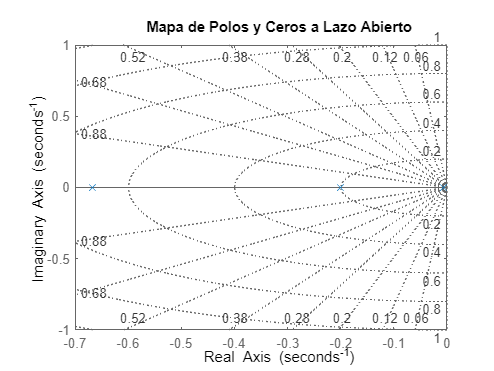

pzmap(GH);  % Muestra el mapa de polos y ceros de la funcion a lazo abierto
title('Mapa de Polos y Ceros a Lazo Abierto');
grid on;


%El sistema es absolutamente estable, todas las reacies de la ecuacion
%caracteristicas estan en el semiplano negativo

%Desde el punto de vista relativo es marginalmente estable, solo es estable
%para kp<1450

%Lugar de raices del GH
figure;
rlocus(GH);
rlocfind(GH);

Select a point in the graphics window


selected_point = 0.0017 + 0.3570i

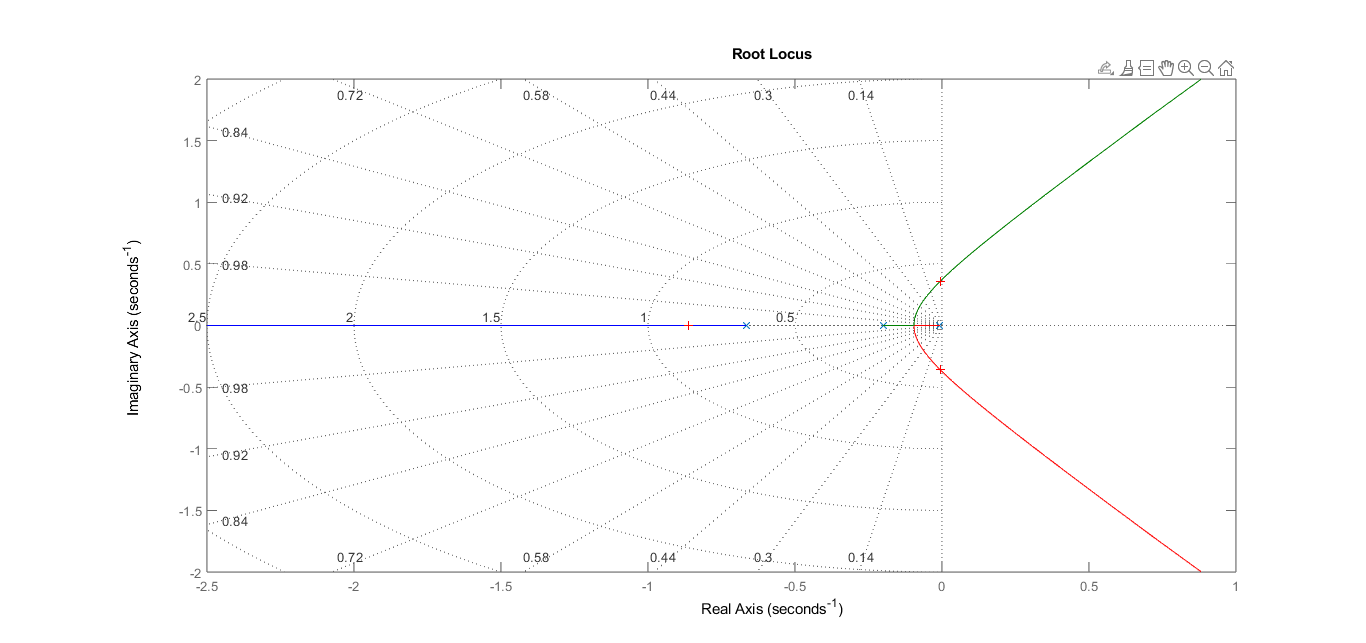

grid on;

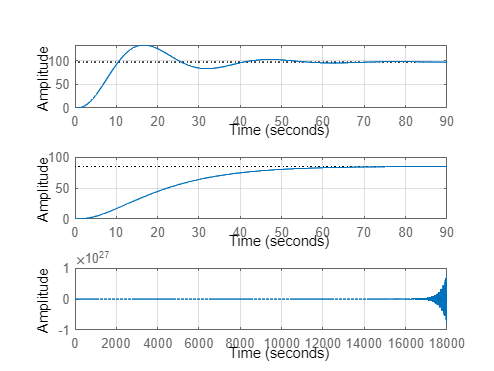


k1=400;
k2=62;
k3=1500;

% Verificamos la estabilidad realtiva
figure;
% Primer subplot: Respuesta para k1
subplot(3, 1, 1);
step(feedback(k1 * G, H));
title('');
grid on;

% Segundo subplot: Respuesta para k2
subplot(3, 1, 2);
step(feedback(k2 * G, H));
title('');
grid on;

% Tercer subplot: Respuesta para k3
subplot(3, 1, 3);
step(feedback(k3 * G, H));
title('');
grid on;


%-------------------------------------------------Diseño compensador
%Requermientos ts=min ess=min mp=0


%Forma general del compensador PD=





















